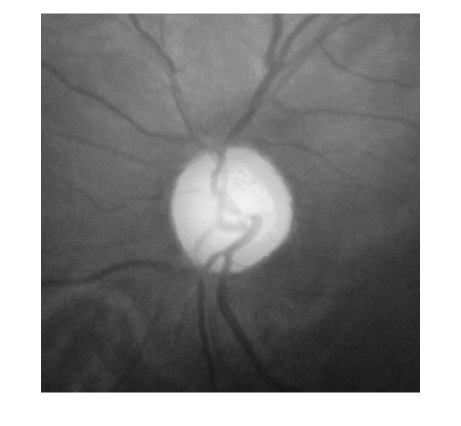

%Open file
[image, pathname] = uigetfile('*.png');
J = imread(image);

%Crop gambar untuk menghilangkan border hitam pada gambar asli
I = imcrop(J,[350 350 1250 1250]);
HSV = rgb2hsv(I);

%%Cek RGB
R = I(:,:,1);
G = I(:,:,2);
B = I(:,:,2);

figure, imshow(R)

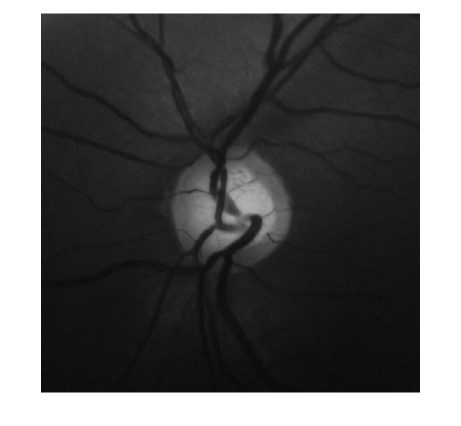

figure, imshow(G)

figure, imshow(B)

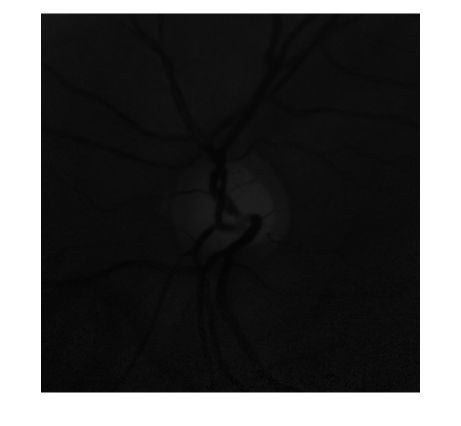


%%Cek HSV
H = HSV(:,:,1);
S = HSV(:,:,2);
V = imadjust(HSV(:,:,3));

figure, imshow(H)

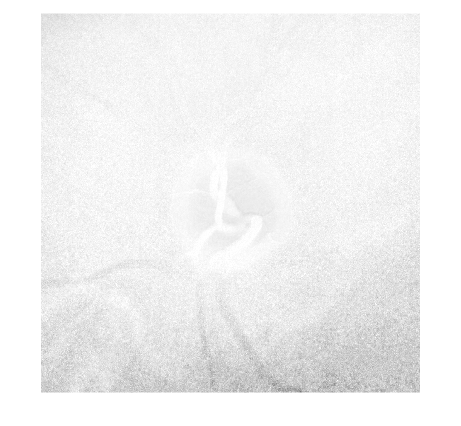

figure, imshow(S)

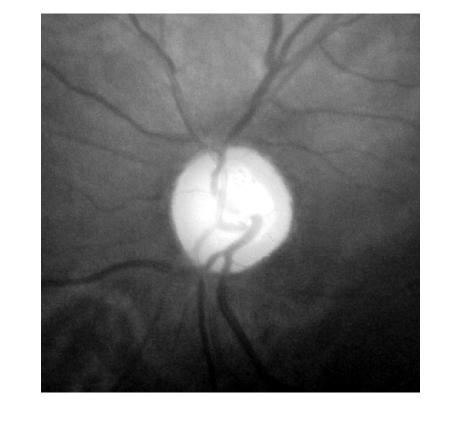

figure, imshow(V)

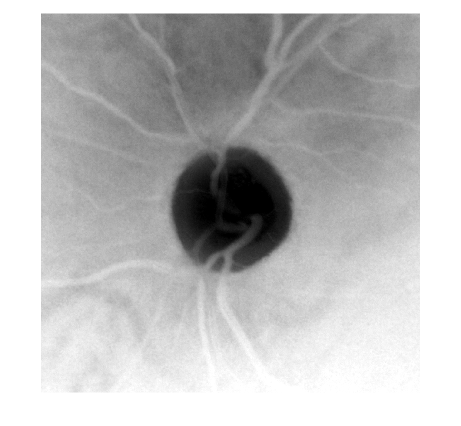


%Disimpulkan untuk lokalisasi dan segmentasi menggunakan nilai Value citra
%Ambil value citra
%Invert warna
figure, imshow(imcomplement(V))

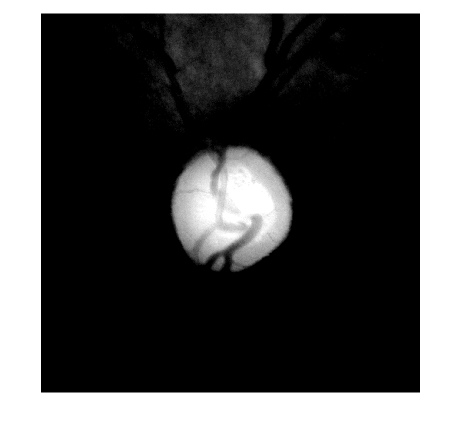

%Mengubah kontras citra gray
Vnew = V - imcomplement(V);
figure, imshow(Vnew)

level = graythresh(V);
%Vnew = imadjust(Vnew);
ne = Vnew > level;
binaryImage = ne;
% Get rid of stuff touching the border
binaryImage = imclearborder(binaryImage);
fill = imfill(binaryImage,'holes');

se = strel('disk', 6)

se = strel is a disk shaped structuring element with properties:

      Neighborhood: [11×11 logical]
    Dimensionality: 2


dil = imdilate(fill,se)

dil = 1251×1251 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0  

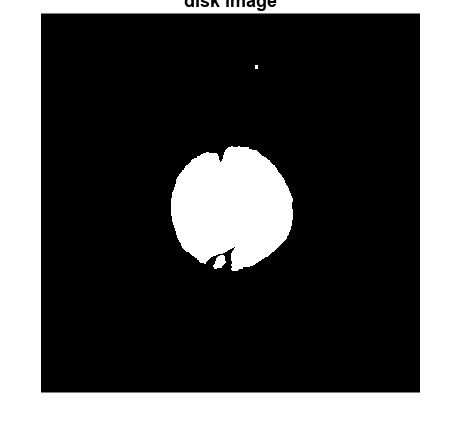

figure,imshow(dil)
title('disk image')


N = nnz(dil);
fprintf('Luas OD = %i Pixel\n', N)

Luas OD = 125330 Pixel



openim = imclose((imopen(dil, strel('diamond',25))), strel('arbitrary',40))

openim = 1251×1251 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   

% Extract only the two largest blobs.
BW = binaryImage;
CC = bwconncomp(BW);
numPixels = cellfun(@numel,CC.PixelIdxList);
[biggest,idx] = max(numPixels);
BW(CC.PixelIdxList{idx}) = 0;
filteredForeground = BW;

% regionprops untuk mendapatkan informasi Area, Centroid, Bbox
s = regionprops(dil,'basic');
centroids = cat(1,s.Centroid);
bbox = cat(1,s.BoundingBox);
x = s(1).Centroid(1,1) - 1/2*(bbox(3));
y = s(1).Centroid(1,2) - 1/2*(bbox(4));
binr = imcrop(openim, [x y bbox(3) bbox(4)])

binr = 441×708 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   

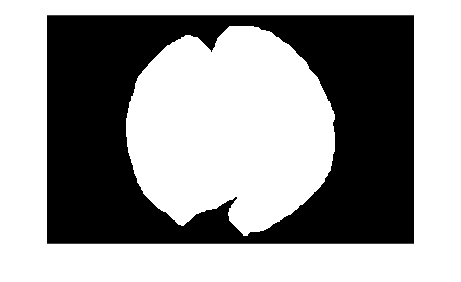

figure, imshow(binr)

fprintf('Panjang (x) Bounding Box = %i Pixel\n', bbox(3))

Panjang (x) Bounding Box = 7.065000e+02 Pixel


fprintf('Panjang (y) Bounding Box = %i Pixel\n', bbox(4))

Panjang (y) Bounding Box = 4.395000e+02 Pixel


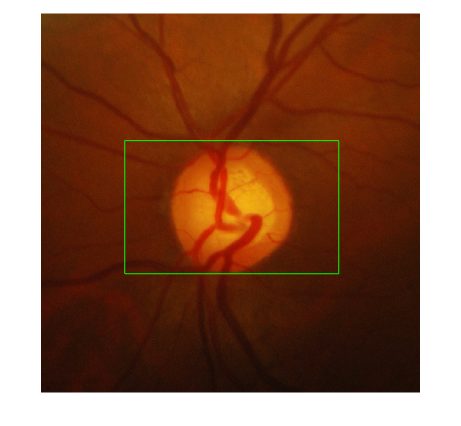



figure, imshow(I)
rectangle('Position',[x y bbox(3) bbox(4)],'EdgeColor','g')

%hold off
% Hitung Area, Luas BoundingBox, Titik tengah
fprintf('Area = %i Pixel\n', s(1).Area);

Area = 123947 Pixel


fprintf('Luas = %i Pixel^2\n', bbox(3)*bbox(4));

Luas = 3.105068e+05 Pixel^2


fprintf('Titik Pusat = (%i, %i) Pixel\n', s(1).Centroid(1,1), s(1).Centroid(1,2));

Titik Pusat = (6.302706e+02, 6.397898e+02) Pixel



% figure, imshow(BW);
% % Fill holes in the blobs to make them solid.
%binaryImage = imfill(binaryImage, 'holes');
% % Display the binary image.
%dis(:,:,1)=immultiply(binaryImage,I(:,:,1));
%dis(:,:,2)=immultiply(binaryImage,I(:,:,2));
%dis(:,:,3)=immultiply(binaryImage,I(:,:,3));
%a = dil;
%stats = regionprops(double(a),'Centroid',...
%    'MajorAxisLength','MinorAxisLength')
%centers = stats.Centroid;
%diameters = mean([stats.MajorAxisLength stats.MinorAxisLength],2);
%radii = diameters/2;
% Plot the circles.
% figure,imshow(I)
%hold on
%viscircles(centers,radii);
%hold off

%Menentukan Luas OC
crpd = imcrop(I, [x y bbox(3) bbox(4)])

crpd = 441×708×3 uint8 array
crpd(:,:,1) =

   112   114   113   112   112   112   112   114   115   115   115   115   113   112   114   114   115   116   115   115   114   115   117   116   117   117   117   118   114   110   112   116   113   110   114   116   118   116   115   117   117   115   115   117   116   116   115   114   114   113   112   121   121   118   117   117   118   118   114   118   118   115   112   113   115   119   122   121   115   111   112   115   114   112   113   113   115   118   120   120   118   120   115   115   115   114   114   113   111   111   111   112   112   115   117   116   117   118   117   117   115   111   113   118   114   110   116   116   113   114   116   115   114   113   111   114   112   112   113   113   114   116   114   113   116   118   116   110   110   111   110   112   112   113   111   110   108   108   108   107   107   106   107   109   109   108   109   106   108   107   104   104   106   107   106   108   106   107   109  

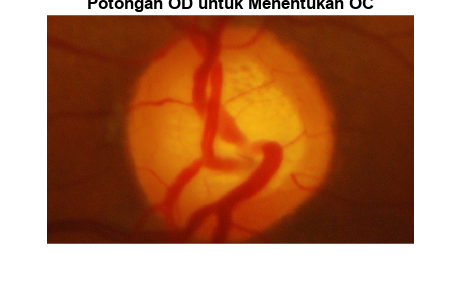

figure, imshow(crpd)
title('Potongan OD untuk Menentukan OC');

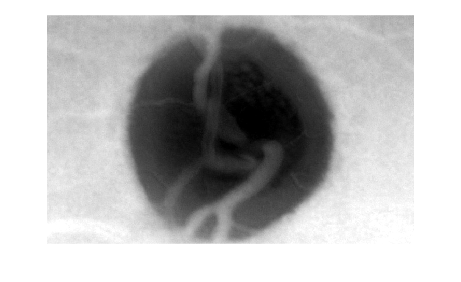


%Invert warna
HSV = rgb2hsv(crpd);
V2 = HSV(:,:,3);
figure, imshow(imcomplement(imadjust(V2)))

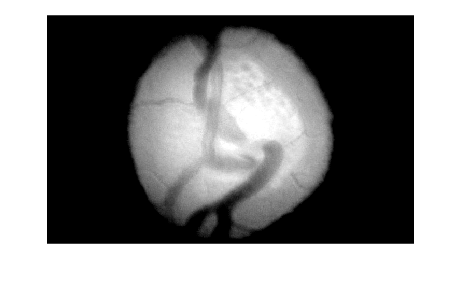

%Mengubah kontras citra gray
V2new = imadjust(V2 - imcomplement(imadjust(V2)));
figure, imshow(V2new)

%Vnew = imadjust(Vnew);
ne = Vnew > level2;
binaryImage = ne;
% Get rid of stuff touching the border
binaryImage = imclearborder(binaryImage);
fill = imfill(binaryImage,'holes');

se = strel('disk', 8)

se = strel is a disk shaped structuring element with properties:

      Neighborhood: [15×15 logical]
    Dimensionality: 2


cup = imdilate(fill,se)

cup = 1251×1251 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0  

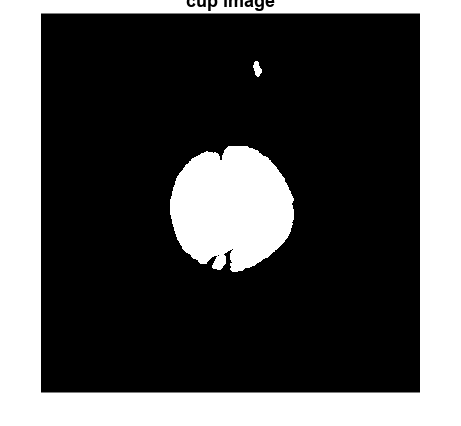

figure,imshow(cup)
title('cup image')